`load images as data store`

`imageDatastore() labels images based on folder name automatically`

path = 'D:\workspace\MATLAB\DAN2019\DAN2019\images';
imds = imageDatastore(path, ... 
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

`number of images for training`

numTrainImages = numel(imds.Labels);

`AlexNet default input image size is 227×227×3, where 3 refers to the three channels of color pictures`

for i = 1:numTrainImages
    s = string(imds.Files(i));
    I = imread(s);
    I = imresize(I,[227,227]);
    imwrite(I,s);
end

`The data is divided into training and validation data sets: 70% of images for training and 30% of images for verification`

[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7);

`Generate a random number idx(i), display 4 images`

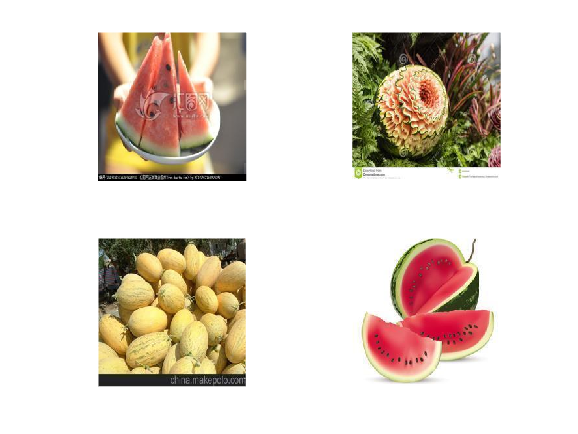

numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,50);
figure(1)
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end